# 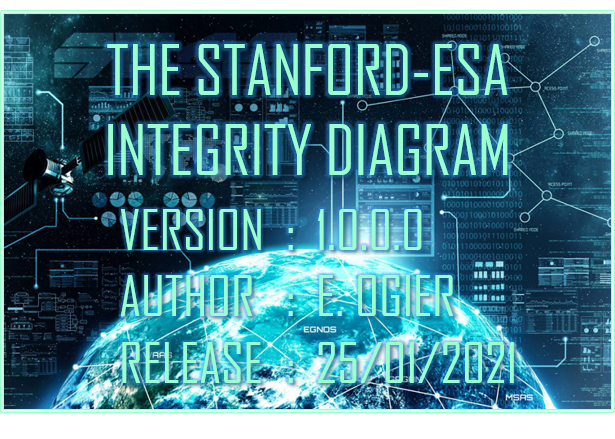

## **Introduction**

StanfordDiagram is a MATLAB class dedicated to the representation of GNSS/SBAS receivers positions errors and protection levels in the Stanford-ESA Integrity Diagram.

The diagram aims at providing:

- a bidimensional histogram, in a regular grid, of the couples of position error (estimated by comparing the position from the GNSS/SBAS receiver) to a reference) and protection level (estimated by the GNSS/SBAS receiver),

- an additional histogram subdivided in SBAS domains (subdivision w.r.t category limit and alert limit) proving epochs and statistics.

For more information about the Stanford-ESA Integrity Diagram, see [The Stanford – ESA Integrity Diagram: Focusing on SBAS Integrity](https://gssc.esa.int/navipedia/index.php/The_Stanford_%E2%80%93_ESA_Integrity_Diagram:_Focusing_on_SBAS_Integrity).

## Settable properties

- **Minimum : **minimum value of position error / protection level (format: numeric scalar; default value: 0).

- **Maximum :** maximum value of position error / protection level (format: numeric scalar; default value: not a number, arbitrary set to 50 if not defined when the diagram is displayed).

- **Step : **step of the sampling between minimum and maximum values of position error / protection level (format: numeric scalar).

- **Edges : **edges for the discretization of position error / protection level (format: numeric vector).

- **Number : **number of edges (format: numeric scalar; default value: not a number, arbitrary set to 100 if maximum is not defined when the diagram is displayed)

- **AlertLimit : **alert limit (format: numeric scalar; default value: empty, i.e. not applicable)

- **CategoryLimit : **category limit, (format: numeric scalar; default value: empty, i.e. not applicable, to be set to subdivide nominal operations in two categories).

- **Axes : **axes in which the diagram is created (default value: empty, new axes if not specified).

- **Scale : **scale of histogram color bar, among 'auto', 'log' and 'linear' (default value: 'auto', value 'auto' is equivalent to 'log' if the maximum of the histogram exceed 100, 'linear' otherwise).

- **Title :** title of the diagram (format: string; default value: 'Stanford-ESA Integrity Diagram').

- **Xlabel :** label of X-axis diagram (format: string; default value: 'Positon Error [m]').

- **Ylabel : **label of Y-axis diagram (format: string; default value: 'Protection Level [m]').

- **Xtick :** ticks of diagram X-axis (format: numeric vector).

- **Xticklabel :** tick labels of diagram X-axis (format: string cell).

- **Ytick :** ticks of diagram Y-axis (format: numeric vector).

- **Yticklabel : **tick labels of diagram Y-axis (format: string cell).

- **FontSize :** fonsize of all labels of diagram.

- **Strings : **strings displayed as domain labels (format: string cell).

- **StringFcns : **string functions complementing the domain labels with epochs and statistics (format: cell of strings or anonymous functions; arguments of anonymous functions: resp. epochs and statistics).

- **Colors : **colors of the domains (format: numeric vector of red/green/blue components, between 0 and 255).

**Notes:**

- The histogram grid can be defined two different ways, by setting the minimum, the maximum and the step or more directly by setting the edges.

- The number of displayed domains depends on the applicability of category limit and alert limit (x2, x5 or x7). The properties relative to domains ('Strings', 'StringFcns' and 'Colors') shall be set as cell, which length is the number of applicable domains.

## Methods

- **StanfordDiagram(Name,Value,...) :** Constructor of the class. The construction can take into account input arguments such as settable properties, position error vector, protection level vector. The inputs shall be defined as pairs of name and value, among the settable properties listed above or **'PositionError'** and **'ProtectionLevel'** (both arguments **'PositionError'** and **'ProtectionLevel'** shall be numeric vectors, with the same length). The diagram is created if position error and protection level are defined otherwise method **'show'** has to be called to display an empty diagram while method **'update' **can be called later to update the diagram with position errors and protection levels.

- **set (Name,Value,...):** method to set properties, defined as pairs of name and value. The setting of the histogram related properties (minimum, maximum, step, edges) is only taken into account visually when method **'update'** is called.

- **show() : **method to show the diagram when empty, in the case the constructor was called without specifying position error and protection level.

- **update(PositionError,ProtectionLevel) :** method to update the diagram with additional couples of position error and protection level are defined as numeric vectors. Arguments **'PositionError' **and** 'ProtectionLevel'** shall be directly in this order, as numeric vectors.

- **reset () :** method to reset the diagram. Once reset, the diagram can be updated through method **'update'**.

- **report () :** method to generate a report providing epochs and statistics of the relevant domains. If an output argument is defined, the report is output in a table, otherwise, it is displayed in the command window.

## Example #1: Stanford diagram with two domains 

- **Synthesis of random position errors and protection levels**

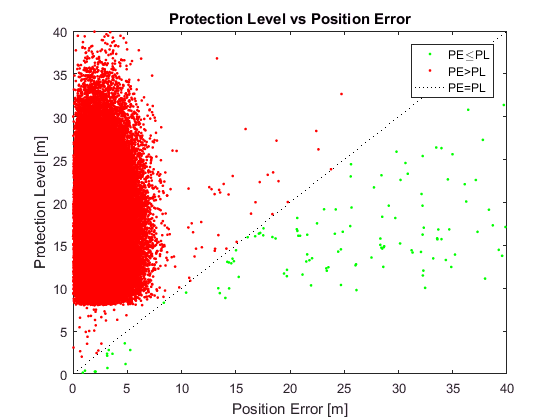

% Generation of random position errors and protection levels (Rayleigh distributions with additional uniform distributions)
N1 = 1e5;
N2 = 200;
E  = [   1*raylrnd(  2,1,N1) 40*rand(1,N2)];
PL = [8+15*raylrnd(0.5,1,N1) 40*rand(1,N2)];

% Permutation of indices to make the applied distribution random
E  = E(randperm(N1+N2));
PL = PL(randperm(N1+N2));

% Indices of the couples so that position errors are inferior or equal protection levels
I = find(gt(E,PL));
    
% Indices and vectors between the corresponding protection levels and position errors
Iple = reshape([I;I;NaN(1,numel(I))],1,[]);
PLE  = reshape([E(I);PL(I);NaN(1,numel(I))],1,[]); 

% Representation
Axes = axes('NextPlot','Add','Box','On');
plot(Axes,E,'b');
plot(Axes,PL,'g');
plot(Axes,Iple,PLE,'r-+')
xlabel('Time step');
ylabel('Value [m]');
legend('PE','PL','PL\rightarrowPE (PE>PL)');

- **Represe****ntat****i****on o****f**** the couples of position ****er****rors and protection levels**

close();

% Indices of couples such as position errors are inferior or equal protection levels
ILE = gt(E,PL);

% Indices of couples such as position errors are superior to protection levels
IGT = le(E,PL);

% Axes limit
L = [0 max(ceil(E))];

% Plot of couples of position errors and protection levels
Axes = axes('NextPlot','Add','Box','On');
plot(Axes,E(ILE),PL(ILE),'g.');
plot(Axes,E(IGT),PL(IGT),'r.');
plot(Axes,L,L,'k:');
set(Axes,'xlim',L,'ylim',L);
title('Protection Level vs Position Error');
xlabel('Position Error [m]');
ylabel('Protection Level [m]');
legend('PE\leqPL','PE>PL','PE=PL');

- **Stanford-ESA Integrity Diagram**

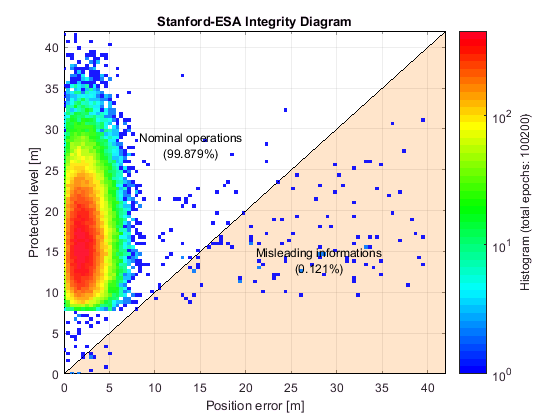

close();

% Stanford diagram
SD = ...
    StanfordDiagram('Axes',            axes(),...
                    'Strings',         {'Nominal operations','Misleading informations'},...
                    'StringFcns',      repmat({@(e,s)sprintf('%s(%.3f%%)',char(10),100*s)},1,2),...
                    'FontSize',        9,...
                    'PositionError',   E,...
                    'ProtectionLevel', PL);    

## **Example #2: Stanford diagrams with four different configurations of domains**

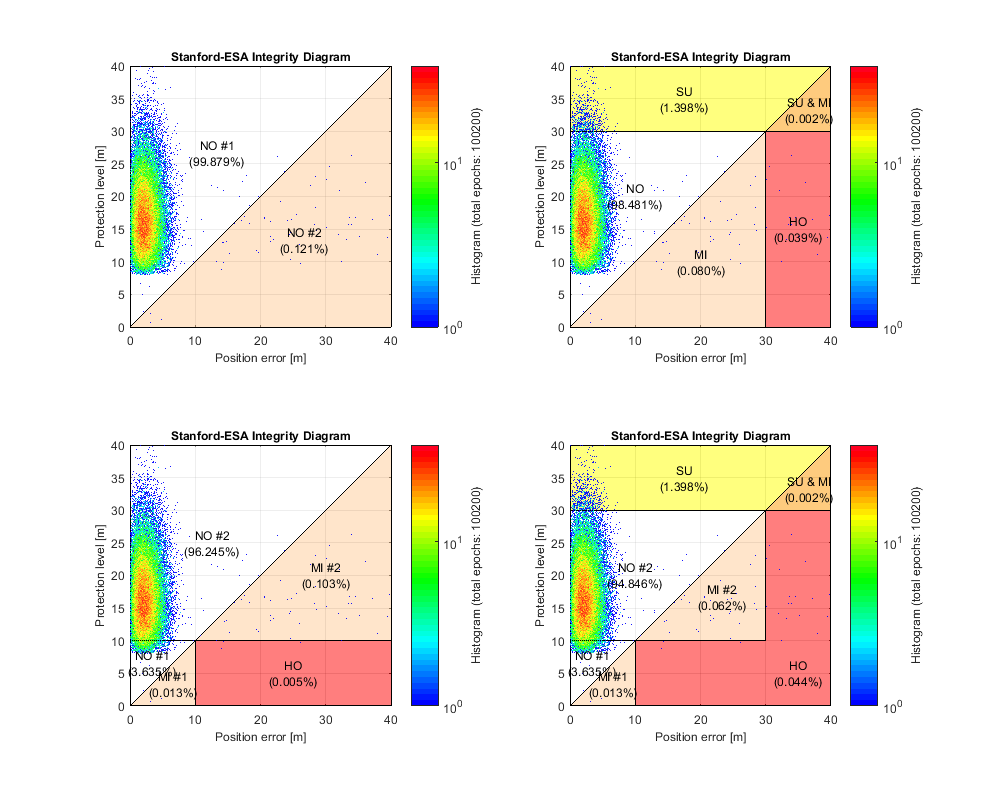

close();

% Figure position
L = 1000;
H = 800;
Position = get(0,'screensize');
Position = [(Position(3)-L)/2 (Position(4)-H)/2 L H];

% Figure
Figure = ...
    figure('Color',      'w',...
           'NumberTitle','Off',...
           'Name',       '',...
           'Position',   Position);
      
% Display function           
Display = @(e,s)sprintf('%s(%.3f%%)',char(10),100*s);         
       
% Display of four diagrams with different configuration
for n = 1:4
        
    switch n
        case 1
            % No alert limit, no category limit
            AlertLimit = []; CategoryLimit = [];
            Strings = {'NO #1','NO #2'};
        case 2
            % Alert limit only
            AlertLimit = 30; CategoryLimit = [];
            Strings = {'NO','SU','MI','SU & MI','HO'};
        case 3
            % Categoty limit only
            AlertLimit = []; CategoryLimit = 10;
            Strings = {'NO #1','NO #2','MI #1','MI #2','HO'};
        case 4
            % Alert limit and category limit
            AlertLimit = 30; CategoryLimit = 10;
            Strings = {'NO #1','NO #2','SU','MI #1','MI #2','SU & MI','HO'};
    end
    
    % Current axes
    Axes = subplot(2,2,n);
    set(Axes,'DataAspect',[1 1 1]);
    
    % Current Stanford diagram
    StanfordDiagram('Axes',            Axes,...
                    'Step',            0.1,...
                    'Maximum',         40,...
                    'AlertLimit',      AlertLimit,...
                    'CategoryLimit',   CategoryLimit,...
                    'Scale',           'Log',...
                    'Strings',         Strings,...
                    'StringFcns',      repmat({Display},1,7),...
                    'FontSize',        9,...
                    'PositionError',   E,...
                    'ProtectionLevel', PL); 
        
    drawnow();

end